# **Adaptive and Cooperative Adaptive Cruise Control**

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Vehicle Systems 8322 |  Dr. Guvenc | Ohio State University | 10/25/2022

# Background

### Basic Cruise Control, CC

    Basic cruise control is meant to keep a vehicles longitudinal speed constant. The solution, relative to the following cruise control types, is simple. 

### Adaptive Cruise Control, ACC

    Adaptive Cruise Control, ACC, has the purpose of creating a time gap between two vehicles travelling one in front of the other. Time gap is the amount of time the lagging vehicle would travel before colliding with a suddenly stopping lead vehicle. From historical research, a time gap of 0.6 seconds to 1.1 seconds is achievable. 

### Cooperative Adaptive Cruise Control CACC

    CACC has the purpose of considering a group, or platoon, of more than two vehicles, and maintaining smaller time gaps between each pair in comparison to ACC time gaps. 

**String Stability **

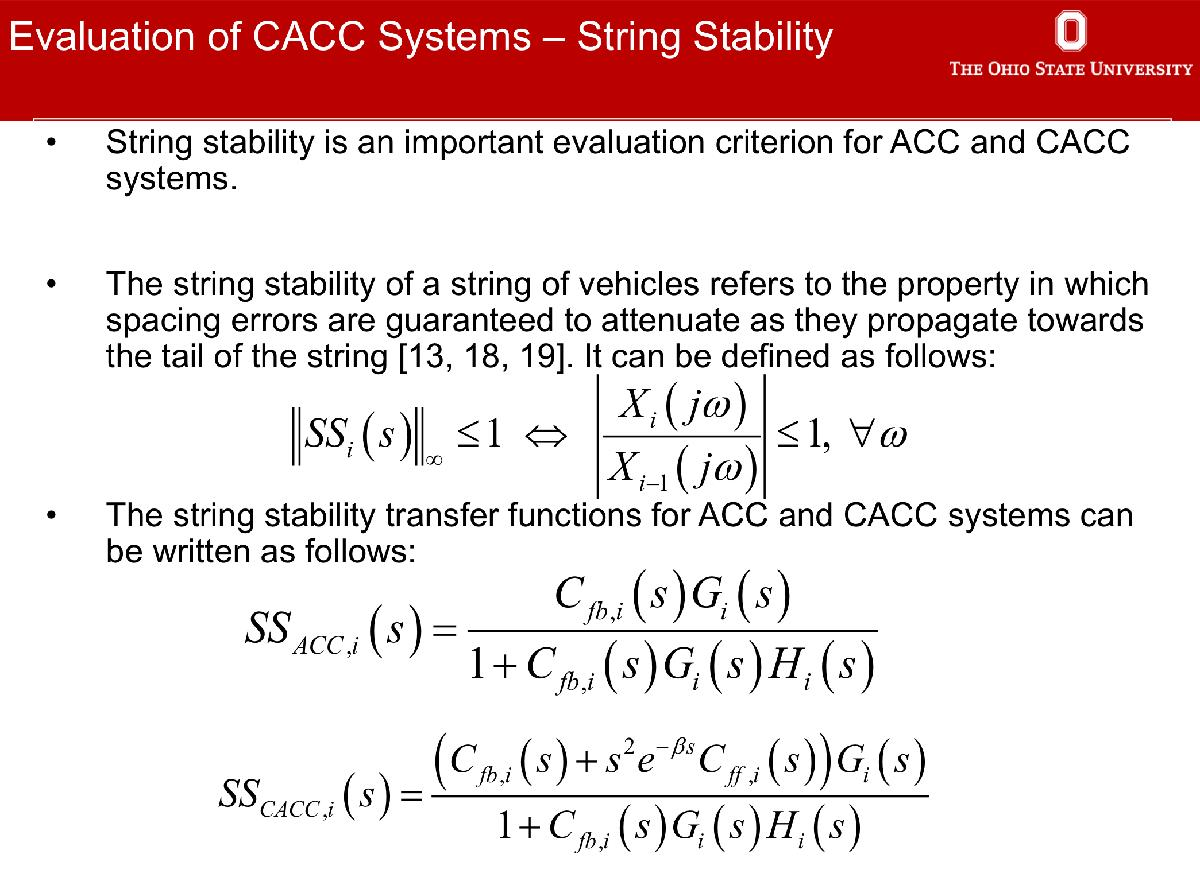

# Start of Script

Variable Clearing

clc; clear; close all;

**Vehicle Transfer Functions: Position, Speed, Acceleration**

- The time constant is assumed 0.3<T<0.7 from historical experimentation

s = tf('s'); K = 1; T = 0.3;
%The Vehicle Position Transfer function
Gp = K / (s^2 * (T*s + 1)); %Position transfer function
%Vehicle Speed Transfer Function
Gv = K/(s*(T*s+1));
%Vehicle Acceleration Transfer Function
Ga = K/(T*s+1);

**H, the feedback path function**

- Insures constant vehicle spacing with zero standstill distance, standstill distance can be changed by modifying the input signal

- the gap time, tauh or Thd is a measure of seconds a lag car would travel before hitting a suddenly stopping lead car. It can be different for each vehicle in CACC

- the vehicle lengths will be taken as zero for a simplification

s = tf('s'); tauh = 0.6; 
H = 1+ tauh*s;

*This feedback path cannot be implemented directly because it is impropper. So it must instead be implemented in the following way*

***The ACC Block Diagram Adapted, using the vehicle velocity plant, no standstill distance***

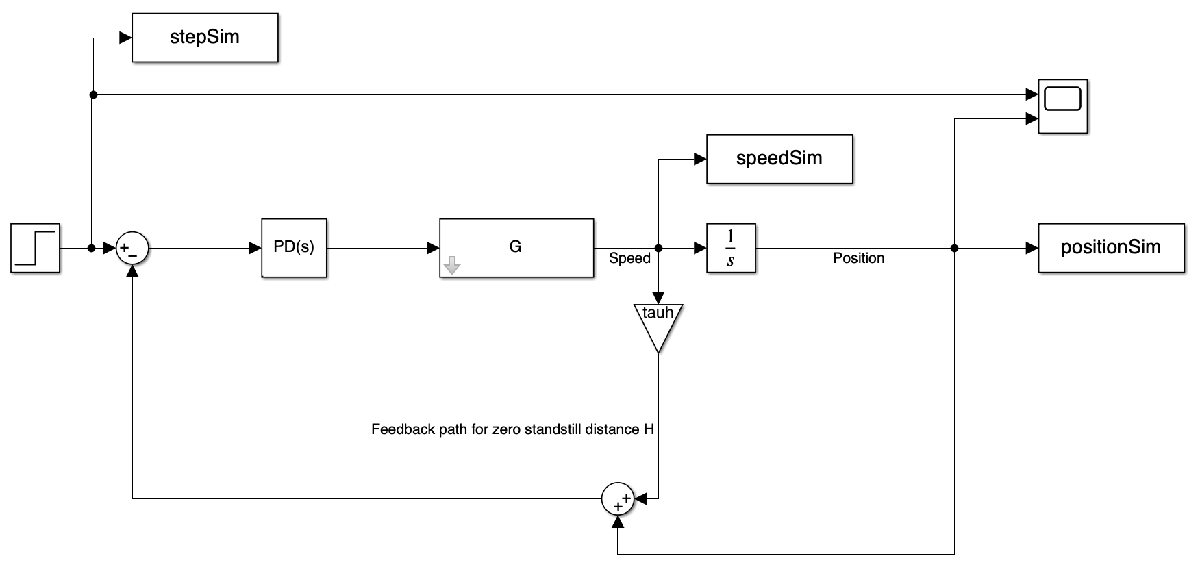

# Controller Tuning

***Adaptive Cruise Control, ACC, Step Response ***

*SIMULINK CALL*

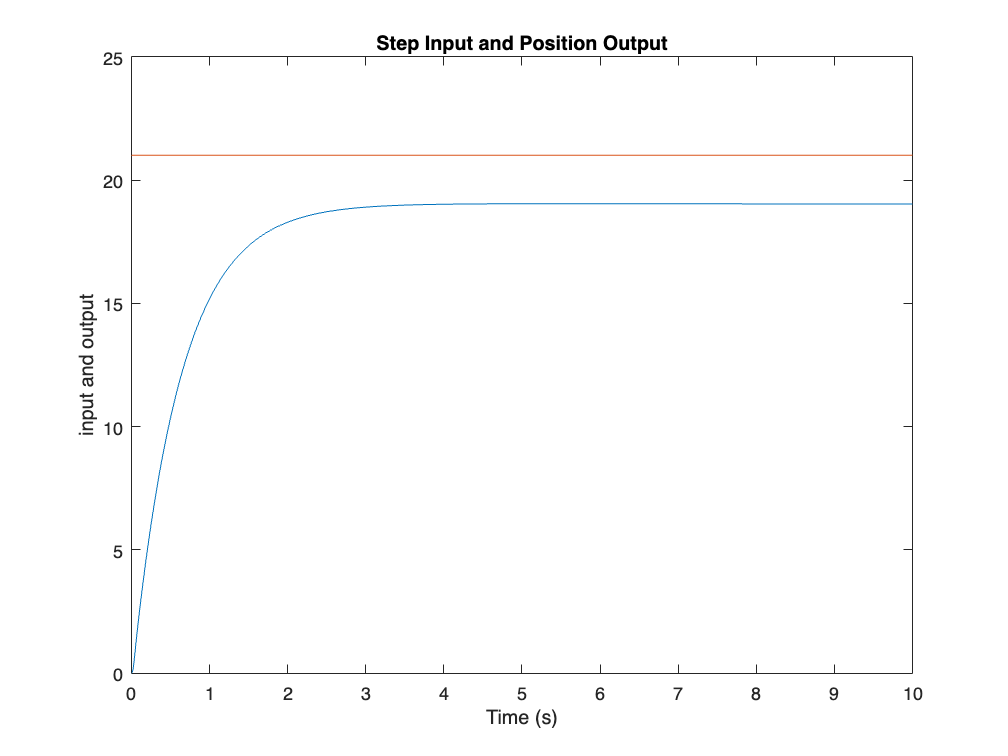

Kp1 = 3; Ki1 = 0; Kd1 = 30; N1=100;
C1 = pid(Kp1,Ki1,Kd1);
sim('ACC.slx');

figure(1), plot(timeSim,positionSim), hold on, plot(timeSim,stepSim)
title('Step Input and Position Output'), xlabel('Time (s)'), ylabel('input and output')

The input step represents the lead vehicle position increasing suddenly.

The output signal is the lag vehicle position. Here, a standstill distance is implemented and the controller is tuned. This controller will be used for subsequent simulations. It was first tuned in simulink and then adjusted here in matlab.

***Adaptive Cruise Control, ACC, Step Response*** 

*Matlab*

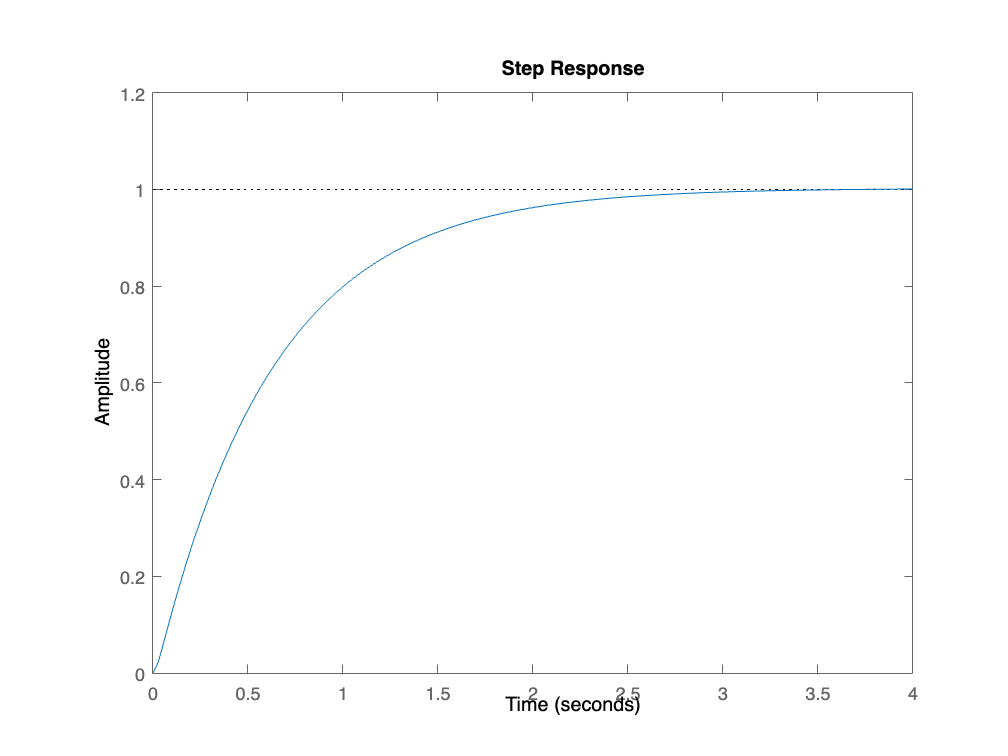

feedback(Gp*C1,H);
figure(2), hold off, step(feedback(Gp*C1,H)) %reminder that Cp is just a gain in this case

This response is slightly different than the previous simulink. This could be investigated further, but is speculated to be differences in simulation stepping times.

# Adaptive Cruise Control, ACC

### Simulate Homogeneous ACC Platooning

    By using a Drive Cycle velocity profile on the ACC system tuned above

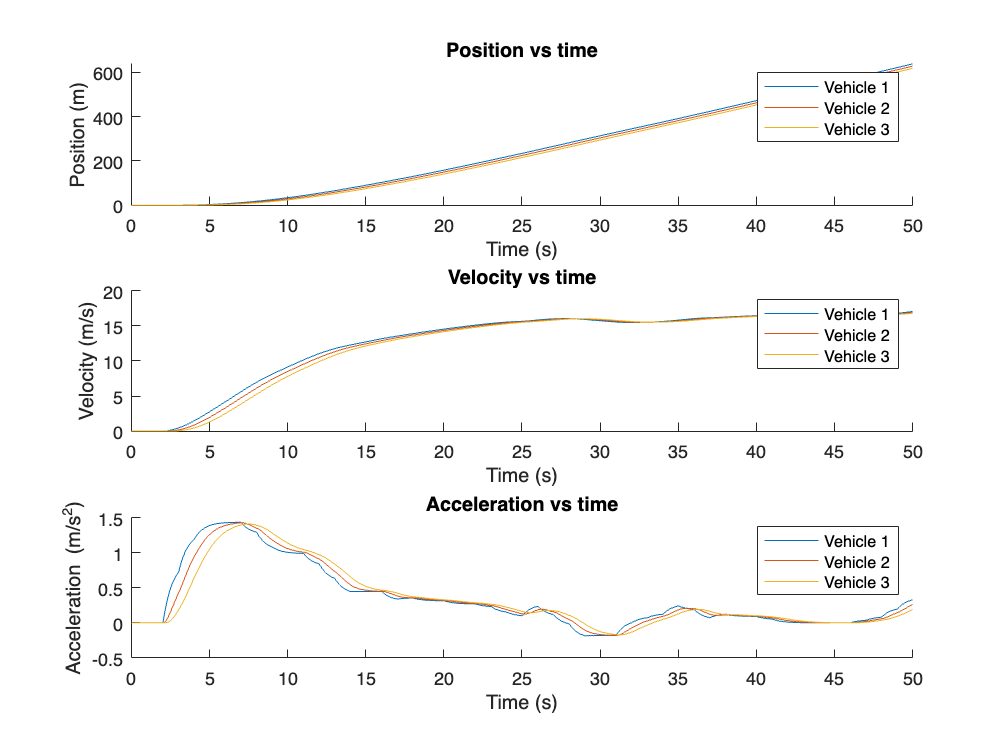

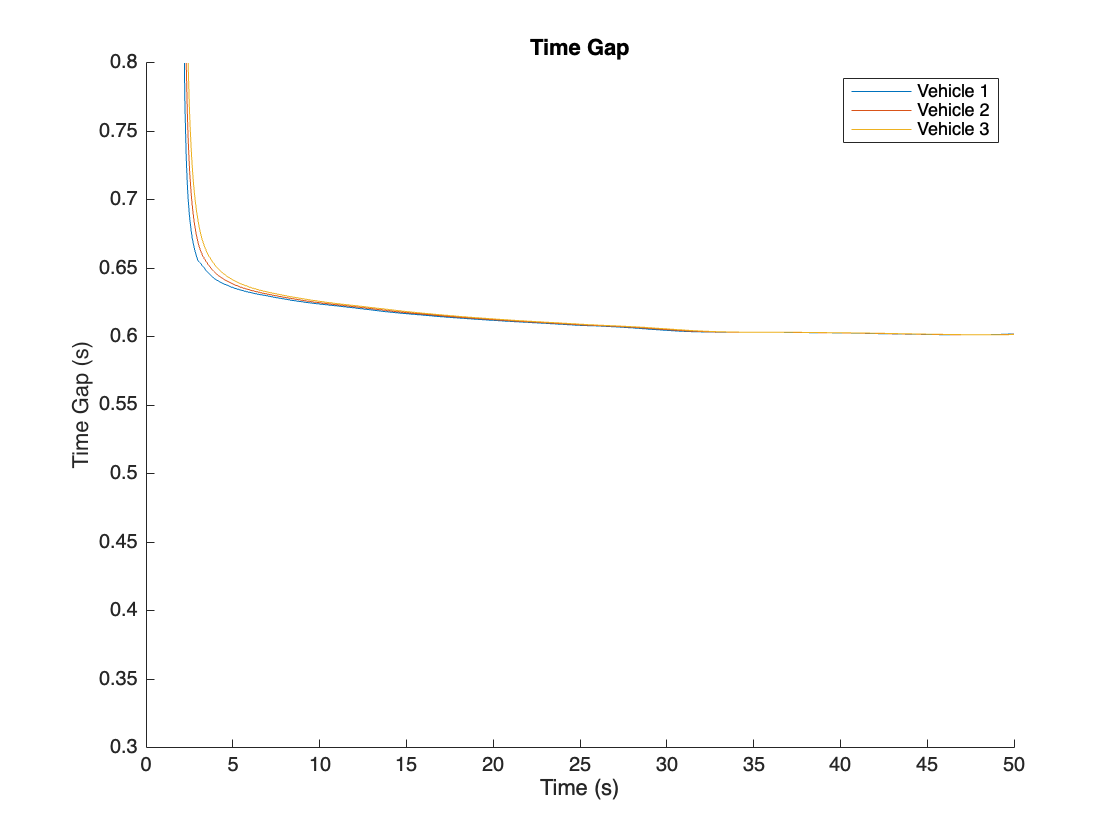

%Making the Plant Time Constants'
T1 = 0.45; T2 = T1; T3 = T1; T = [T1 T2 T3];

file = 'ACC_3_Vehicle_Sim.slx';
[v1_acc_homo v2_acc_homo v3_acc_homo] = simAndPlot(file);

The ACC time gaps are stable and consistent around 1 second for this simulation 

It can be seen that when the vehicles are moving very slow around t=0 seconds, the time gap is very large. It may be useful to ignore this section, add a time delay, or zoom in on the area of interest. Additionally, the time surrounding when the vehicles move slow around 40 seconds, the time gap is also very sensitive - this area has been cut out of the graph.

***String Stability ***

infNorm_SSacc_homo = SSacc(T,C1,H) %Assuming all C's are the same

infNorm_SSacc_homo =     0.9555    0.9555    0.9555


### Simulate Heteregeneous ACC Platooning

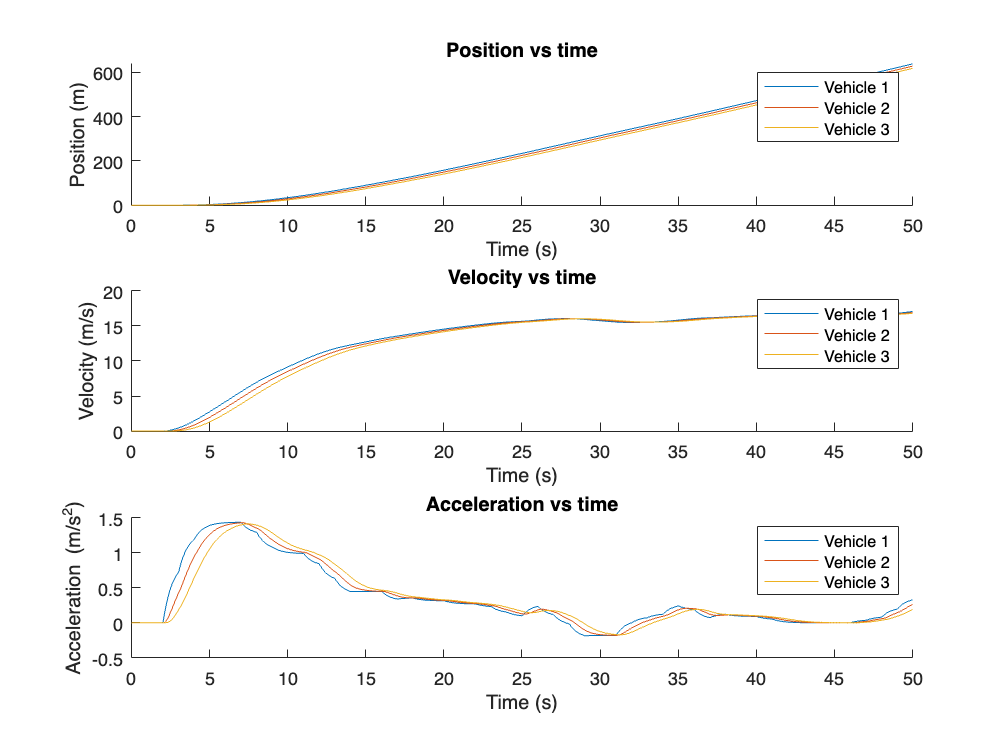

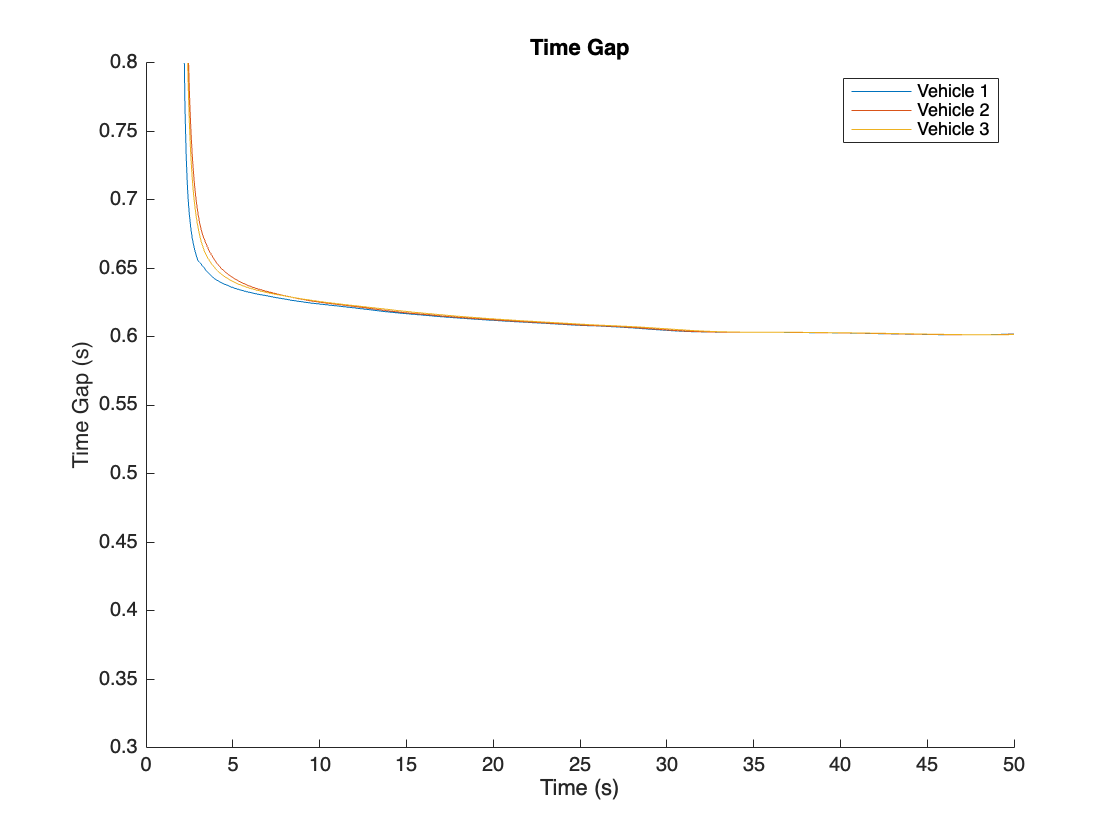

%Making the Plant Time Constants'
T1 = 0.45; T2 = 0.7; T3 = 0.4; T = [T1 T2 T3];

file = 'ACC_3_Vehicle_Sim.slx';
[v1_acc_het v2_acc_het v3_acc_het] = simAndPlot(file);

***String Stability ***

infNorm_SSacc_het = SSacc(T,C1,H) %Assuming all C's are the same

infNorm_SSacc_het =     0.9555    0.9483    0.9570


### CACC Feedback Controller Design

# Cooperative Adaptive Cruise Control, CACC 

*- with the goal of safely reducing time gap, in comparison to ACC*

### ***Homogeneous****** Vehicle Plants, CACC Platooning (vn)***

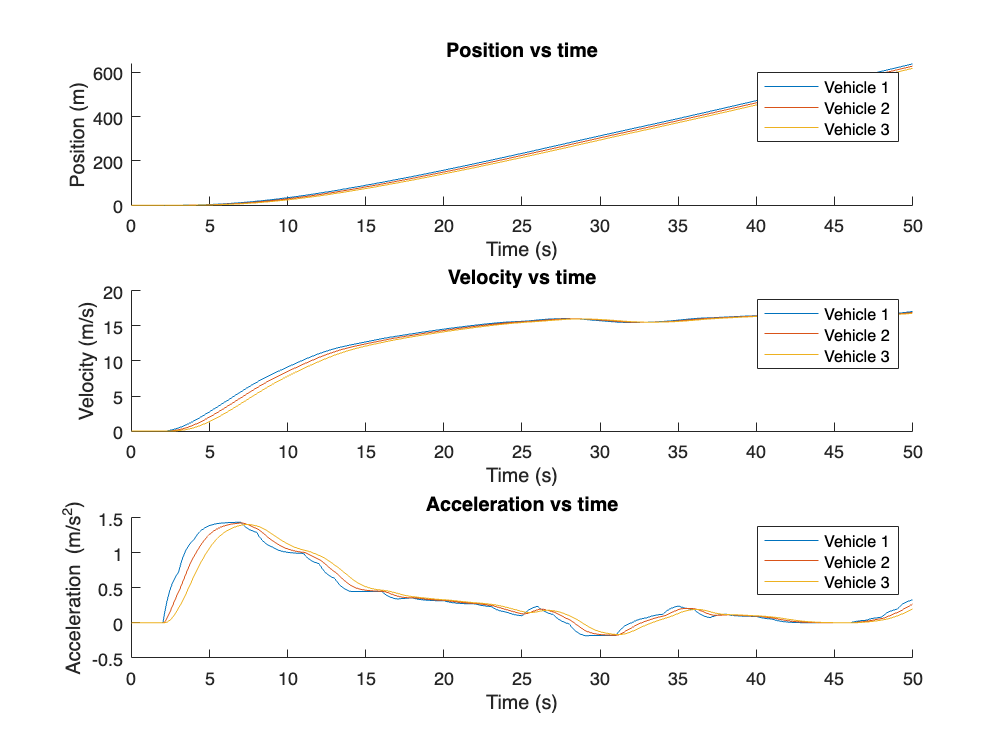

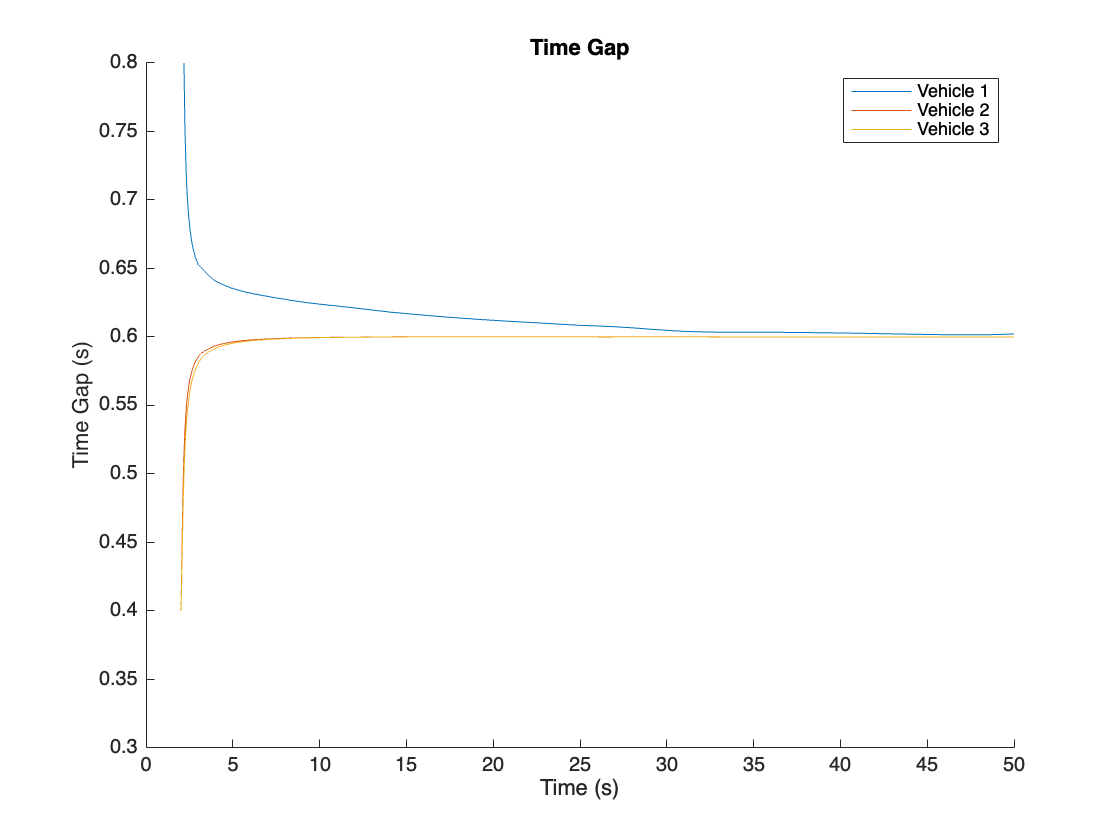

%Vehicle Plant Time Constant
T1 = 0.4; T2 = 0.4; T3 = 0.4;

file = 'CACC_3_Vehicle_Sim.slx';
[v1_cacc_homo v2_cacc_homo v3_cacc_homo] = simAndPlot(file);

Note that the controllers for the CACC acceleration signal have a unity gain, which performed better than the PD controller created earlier

**String Stability**

B = 0; %Time delay measure
infNorm_SScacc_homo = SScacc(T,C1,1,0,H)

infNorm_SScacc_homo =     0.9526    0.9454    0.9541


infNorm_SScacc_homo_time_delay = SScacc(T,C1,1,0.5,H)

infNorm_SScacc_homo_time_delay =     0.9547    0.9475    0.9562


### *Heterogeneous** vehicle plants, CACC Platooning Sim (vncacc)*

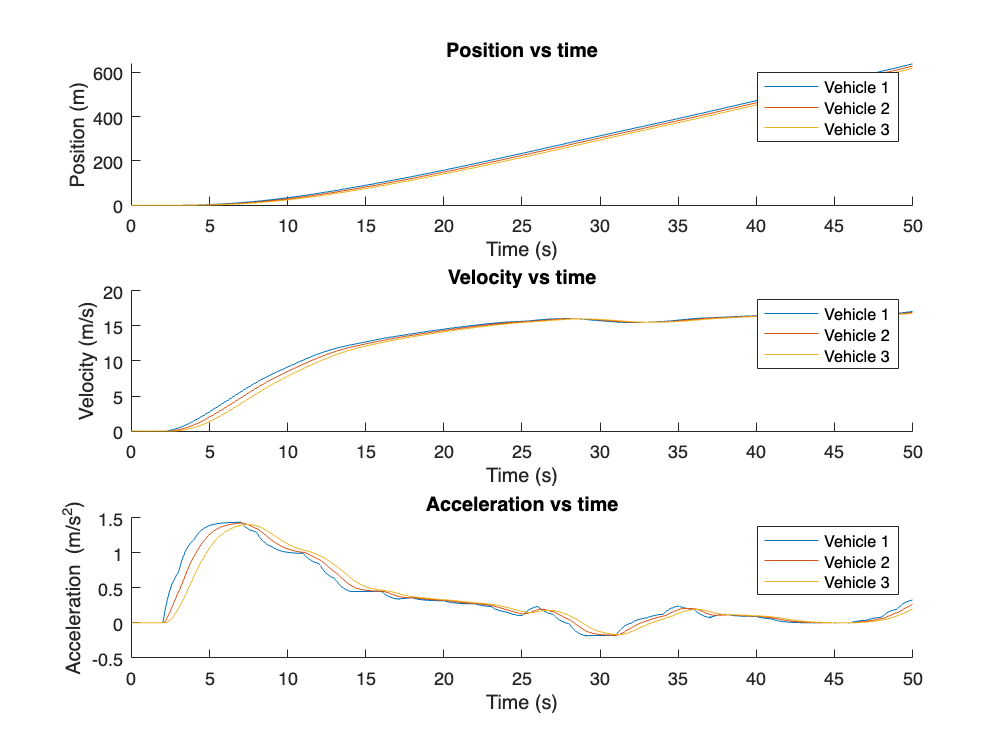

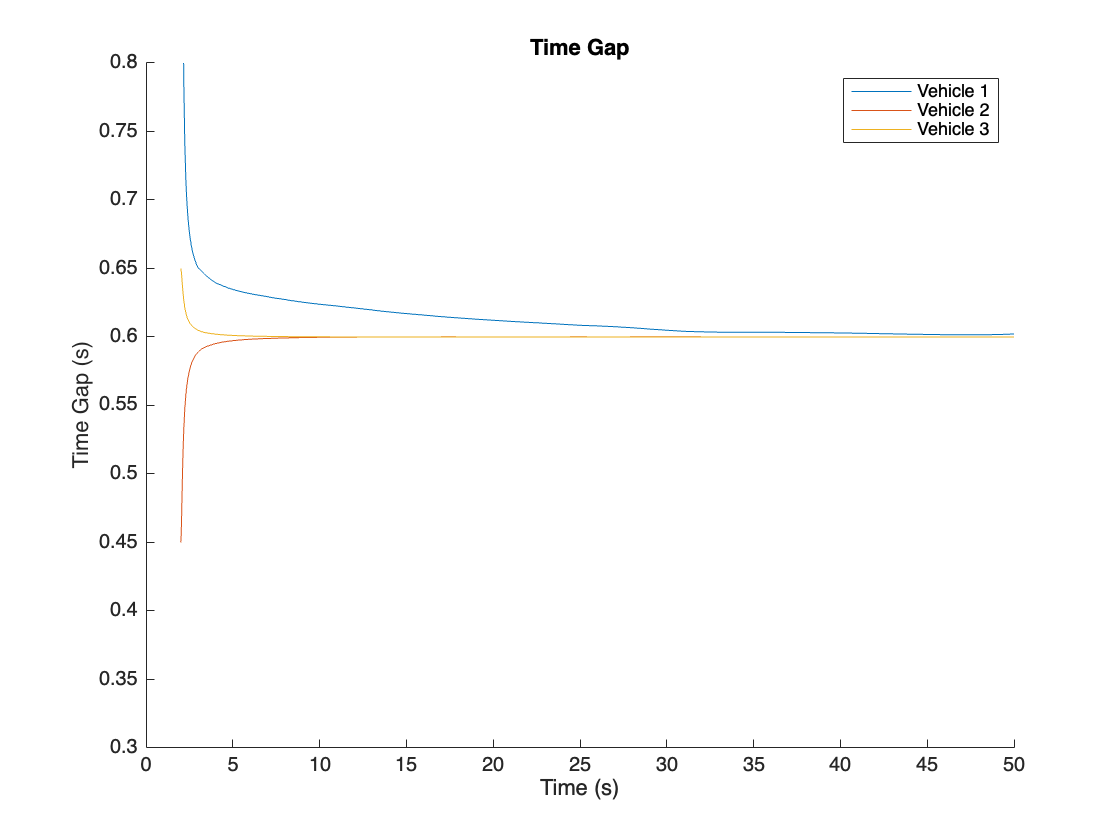

%Time Constants Used
T1= 0.35; T2=0.45; T3=0.65; T = [T1 T2 T3];
file = 'CACC_3_Vehicle_Sim.slx';
[v1_cacc_het v2_cacc_het v3_cacc_het] = simAndPlot(file);

Vehicle 1 is ACC while the consecutive vehicles are CACC, its clear that CACC is much better at keeping the desired time gap

**String Stability**

B = 0; %Time delay measure
infNorm_SScacc_het = SScacc(T,C1,1,0,H)

infNorm_SScacc_het =     0.9555    0.9526    0.9468


infNorm_SScacc_het_time_delay = SScacc(T,C1,1,0.5,H)

infNorm_SScacc_het_time_delay =     0.9577    0.9547    0.9489


### ***Heterogeneous 2****** Vehicle Plants, CACC Platooning Sim***

**    Switching the order of time constants to 0.45 0.65 0.35**

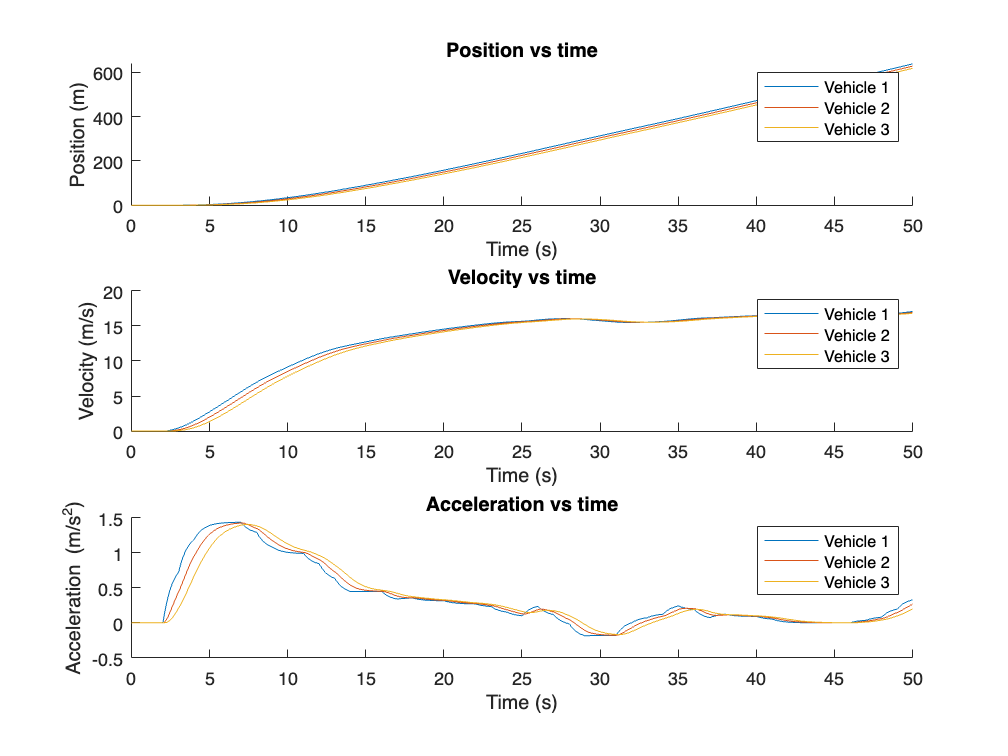

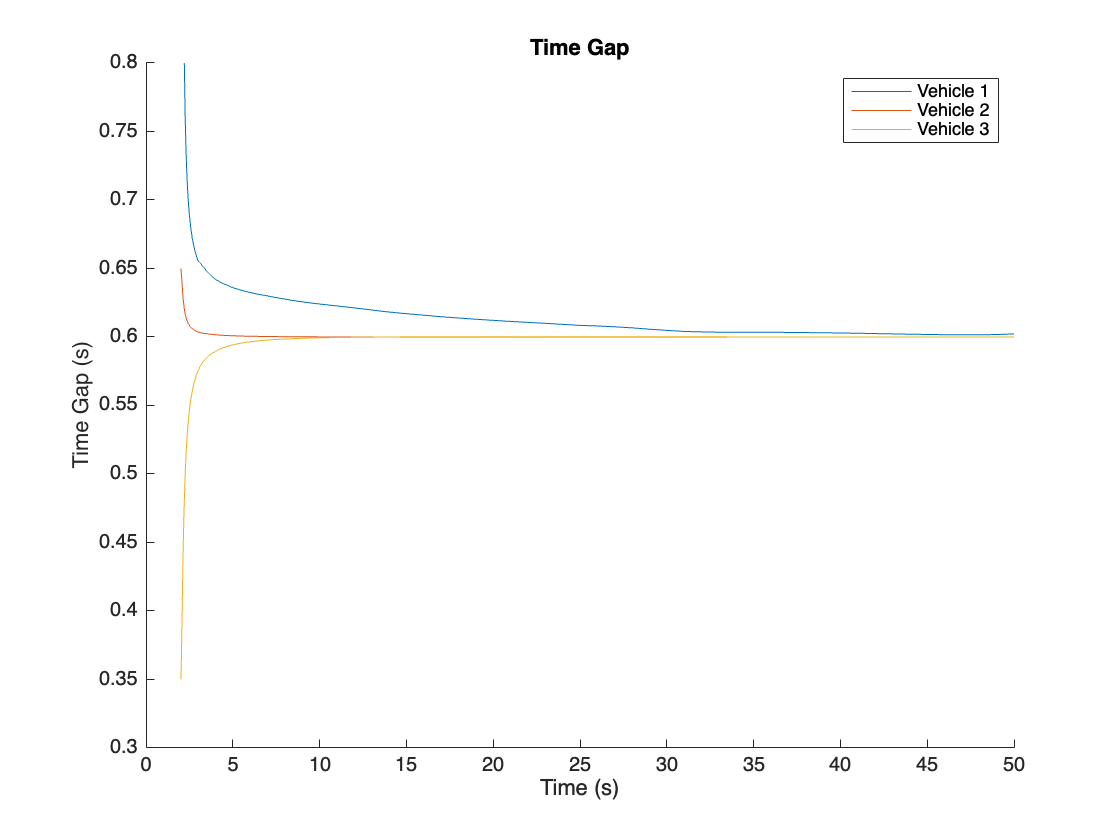

T1= 0.45; T2=0.65; T3=0.35; T = [T1 T2 T3];
file = 'CACC_3_Vehicle_Sim.slx';
[v1_cacc_het2 v2_cacc_het2 v3_cacc_het2] = simAndPlot(file);

**String Stability**

B = 0; %Time delay measure
infNorm_SScacc_het2 = SScacc(T,C1,1,B,H)

infNorm_SScacc_het2 =     0.9526    0.9468    0.9555


infNorm_SScacc_het2_time_delay = SScacc(T,C1,1,0.5,H)

infNorm_SScacc_het2_time_delay =     0.9547    0.9489    0.9577


# Simulation Comparisons

### ***CACC Heterogeneous Sim 1 & 2 Vehicle 3 comparison***

***    Errors propigate to the last vehicle***

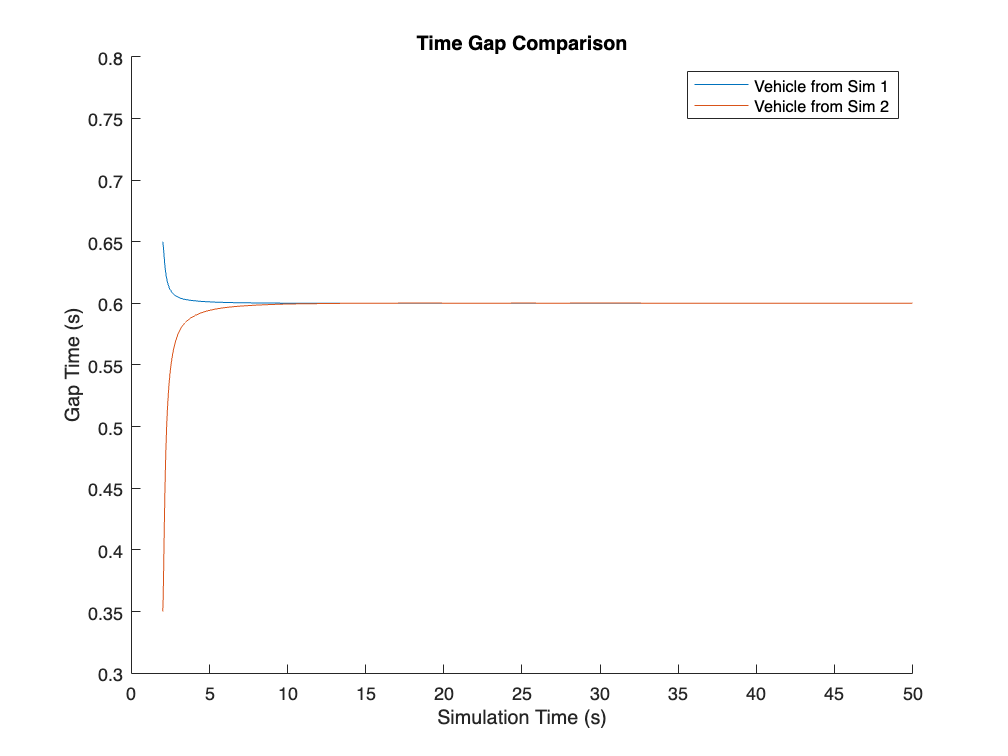

compareTimeGaps(v3_cacc_het,v3_cacc_het2)

The performance in time gap management among the two hetergeneous CACC simualtions does not appear to be significant. Larger platoons or higher differences between vehicle time constants could be investigated.

### ***ACC to CACC Comparison ***

***    Among the ACC and the first CACC vehicles from each sim***

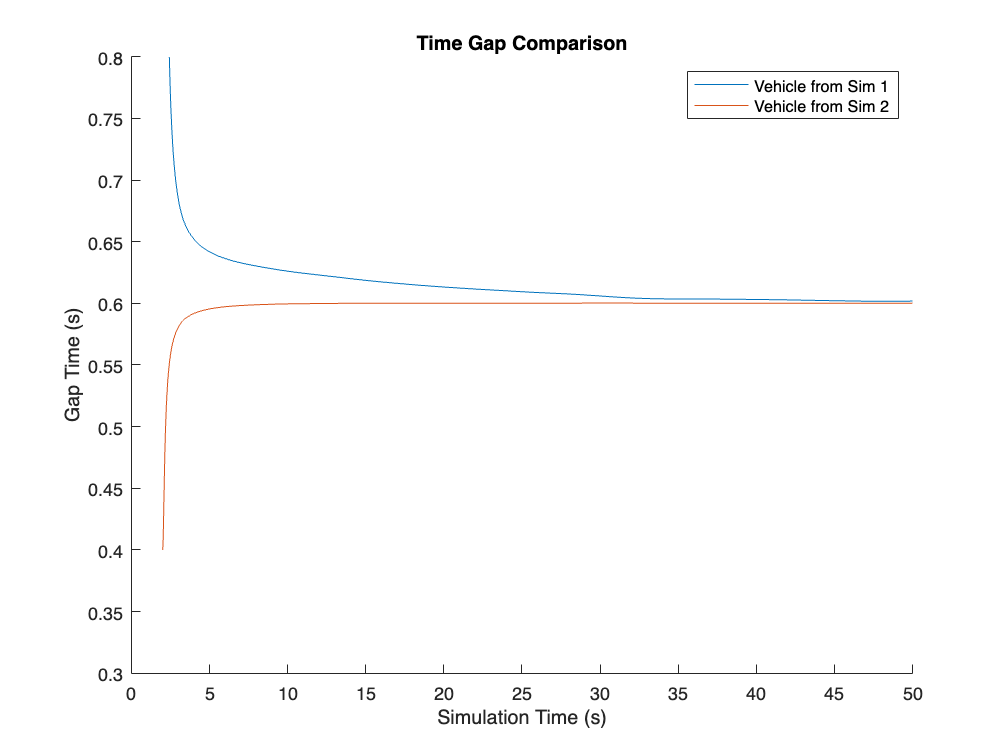

compareTimeGaps(v3_acc_homo,v3_cacc_homo)

## Functions 

function [v1 v2 v3] = simAndPlot(file)
sim(file);
%Converting Sim Data
[v1 v2 v3] = saveSimData(timeSim,Vehicle_1_pos,Vehicle_2_pos,Vehicle_3_pos,Vehicle_1_vel,Vehicle_2_vel,Vehicle_3_vel,Vehicle_1_acc,Vehicle_2_acc,Vehicle_3_acc,timeGap1,timeGap2,timeGap3);
%position, velocity, acceleration plots, and time gap plots
plotVs(v1,v2,v3)
end 

function accelerationTF = aPlant(T);
    %Where T is the plants Time Constant
    s = tf('s'); 
    K = 1; 
    accelerationTF = K/(T*s+1);
end 

function plotVs(v1,v2,v3)
    %where v# is formatted specifically by column: 
        % time position velocity acceleration time_gap
    %Movement Plots
    figure()
    i=2; subplot(311), ploti(i,v1,v2,v3)
    title('Position vs time'), xlabel('Time (s)'), ylabel('Position (m)'), legend('Vehicle 1','Vehicle 2','Vehicle 3')
    i=3; subplot(312), ploti(i,v1,v2,v3)
    title('Velocity vs time'), xlabel('Time (s)'), ylabel('Velocity (m/s)'), legend('Vehicle 1','Vehicle 2','Vehicle 3')
    i=4; subplot(313), ploti(i,v1,v2,v3)
    title('Acceleration vs time'), xlabel('Time (s)'), ylabel('Acceleration (m/s^2)'), legend('Vehicle 1','Vehicle 2','Vehicle 3')
    %Time Gap Plot
    i=5; figure(), ploti(i,v1,v2,v3)
    title('Time Gap'), xlabel('Time (s)'), ylabel('Time Gap (s)'), legend('Vehicle 1','Vehicle 2','Vehicle 3')
    limits = [0 50 0.3 0.8];, axis(limits);
end 
    function ploti(i,v1,v2,v3) 
        hold on, plot(v1(:,1),v1(:,i)), plot(v2(:,1),v2(:,i)), plot(v3(:,1),v3(:,i)), hold off
    end 

function [G1 G2 G3] = setEqual(G1in,G2in,G3in)
    G1=G1in; G2=G2in; G3=G3in;
end

function [v1 v2 v3] = saveSimData(timeSim,Vehicle_1_pos, ...
    Vehicle_2_pos,Vehicle_3_pos,Vehicle_1_vel,Vehicle_2_vel, ...
    Vehicle_3_vel,Vehicle_1_acc,Vehicle_2_acc,Vehicle_3_acc, ...
    timeGap1,timeGap2,timeGap3)
%Rearranging the Simulink Data
i=1; v1(:,i) = timeSim; v2(:,i) = timeSim; v3(:,i) = timeSim;
i=2; v1(:,i) = Vehicle_1_pos; v2(:,i) = Vehicle_2_pos; v3(:,i) = Vehicle_3_pos;
i=3; v1(:,i) = Vehicle_1_vel; v2(:,i) = Vehicle_2_vel; v3(:,i) = Vehicle_3_vel;
i=4; v1(:,i) = Vehicle_1_acc; v2(:,i) = Vehicle_2_acc; v3(:,i) = Vehicle_3_acc;
i=5; v1(:,i) = timeGap1; v2(:,i) = timeGap2; v3(:,i) = timeGap3;
end 

function compareTimeGaps(v1,v2)
    timeGap1 = v1(:,5); timeGap2 = v2(:,5);
    time1 = v1(:,1); time2 = v2(:,1);
    figure(), hold on, plot(time1,timeGap1), plot(time2,timeGap2), hold off
    title('Time Gap Comparison'), xlabel('Simulation Time (s)'), ylabel('Gap Time (s)')
    legend('Vehicle from Sim 1','Vehicle from Sim 2')
    limits = [0 50 0.3 0.8];, axis(limits);
end 

function infNormSSacc = SSacc(T,Cfb,H)
    for i = 1:3
        G(i)  = aPlant(T(i));
        den = 1+ Cfb*G(i)*H;
        SSacc(i) = Cfb*G(i)/den;
        infNormSSacc(i) = norm(SSacc(i),'inf');
    end 
    infNormSSacc;
end 
function infNormSScacc = SScacc(T,Cfb,Cff,B,H)
    s = tf('s'); K = 1;
    for i = 1:3
        G(i)  = aPlant(T(i));
        num = (Cfb + s^2 * exp(-B*s) * Cff)* G(i);
        den = 1+ Cfb*G(i)*H;
        SScacc(i) = num/den;
        if B ==0
        infNormSScacc(i) = norm(SScacc(i),'inf');
        else 
        infNormSScacc(i) = norm(pade(SScacc(i),2),'inf');
        end 
    end 
    infNormSScacc;
end 
